clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');

load modello_1.mat
load modello_2.mat

load controllore_1.mat
load controllore_2.mat

load freq_resp_id_1.mat
load freq_resp_id_2.mat

load identification_1
load identification_2

## Validazione Giunto 1

Cambio portante e segnale eccitante

omega_portante_v1=0.5;
ampiezza_portante_v1=20;
T_portante_v1=2*pi/omega_portante_v1;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t_v1=(0:st:(1.1*T_portante_v1))';
portante_v1=ampiezza_portante_v1*cos(omega_portante_v1*t_v1);
%portante_v_1=ampiezza_portante_v_1*cos(2*pi/120*t_v_1); % sarebbe più opportuno usare un coseno qui
% dato che in identificazione abbiamo usato un seno.

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0_v1=omega_portante_v1*20; %rad/s
w1_v1=pi/st; %rad/s
control_action_validazione1 = chirp(t_v1,w0_v1/2/pi,t_v1(end),w1_v1/2/pi, 'quadratic');
% stessa cosa qui magari usare un cirp quadratico...
ampliezza_validazione1=60;

Sommo i due segnali

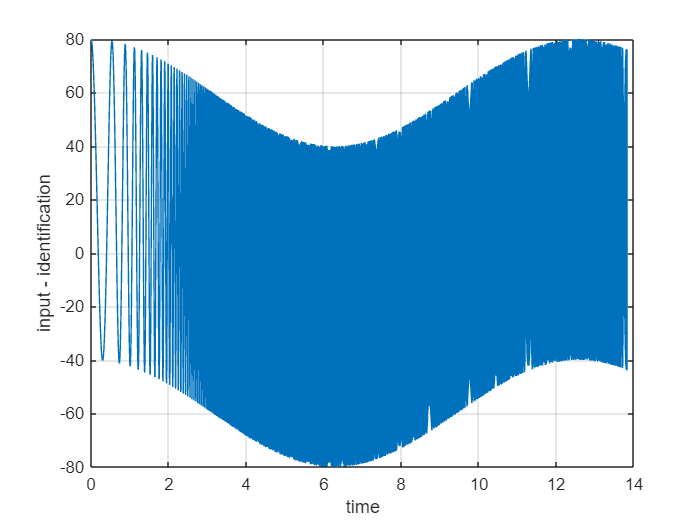

control_action_v1=portante_v1+ control_action_validazione1*ampliezza_validazione1;
figure(1)
plot(t_v1,control_action_v1)
xlabel('time')
ylabel('input - identification')
grid on

cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
x=x0;
s=tf('s');

torque_v1=zeros(length(control_action_v1),2);
process_output_v1=[];
for idx=1:length(t_v1)
    still_ca = controller2.computeControlAction(ref_j0,x(2));
    [x,t_v1(idx,2)]=cs.openloop([control_action_v1(idx) still_ca]);
    process_output_v1(idx,:) = x;
    torque_v1(idx,:) = [control_action_v1(idx) still_ca];
end
toc

Elapsed time is 74.797440 seconds.


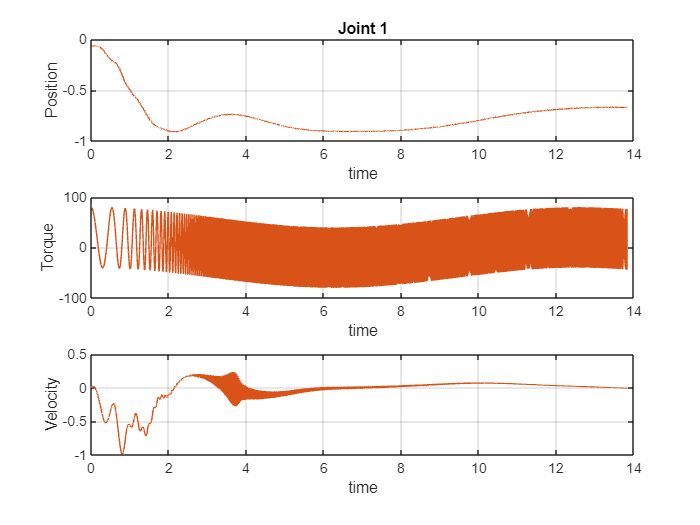

figure(2)
subplot(3,1,1)
plot(t_v1,process_output_v1(:,1))
xlabel('time')
ylabel('Position')
title('Joint 1')
grid on

subplot(3,1,2)
plot(t_v1,torque_v1(:,1))
xlabel('time')
ylabel('Torque')
grid on

subplot(3,1,3)
plot(t_v1,process_output_v1(:,3))
xlabel('time')
ylabel('Velocity')
grid on

### 1.1 Validazione in frequenza

Eseguita con un segnale di eccitazione molto diverso da quello di  identificazione in modo tale da avere una prova significativamente diversa.

**Si fa riconducento la prova come nell'identificazione cambia solo il segnale di eccitazione il resto rimane uguale**.` non va fatta una ristima del modello non avrebbe senso infatti questo è un test per verificare quanto ideale è il modello precedentemente stimato.`

validation1=iddata(process_output_v1(:,3),control_action_v1,st);
freq_resp_vali1 = spafdr(validation1);
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';


Plotto la frequenza di inizio del segnale eccitante

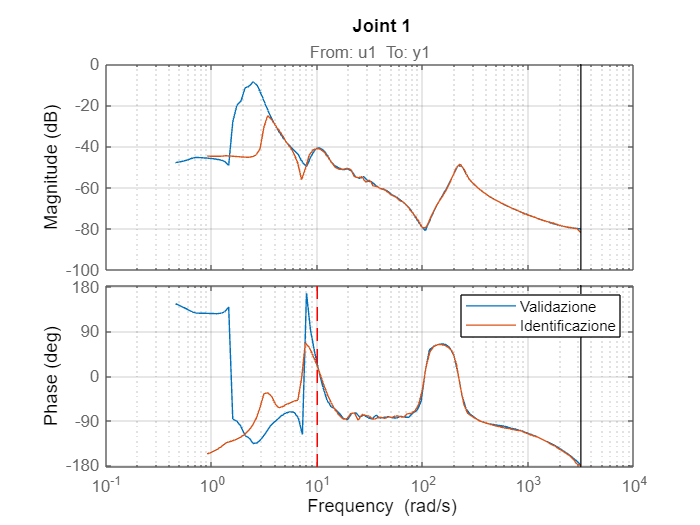

figure(3)
bode(freq_resp_vali1,freq_resp_ident_1,bode_opts)
hold on
plot(w0_v1*[1 1],ylim,'--r')
hold off
grid on
legend('Validazione','Identificazione')
title('Joint 1')

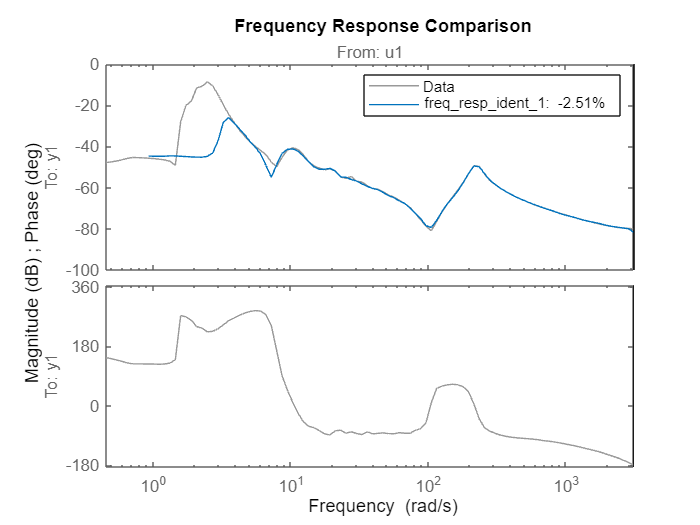

figure(4)
compare(freq_resp_vali1, freq_resp_ident_1)

### 1.3 Identificazione del tempo e la sua bontà nel tempo e in frequenza

E' possibile stimare il modello nel tempo ma:

- è più facile che l'attrito statico ci mandi fuori strada (provare con ampiezza della portante parti a 2 o pari a 0.5)

- non è possibile concentrarsi su un range di frequenze particolare.

usa_terzo_ordine=false;
if (usa_terzo_ordine)
    modello_discreto_tempo1 = ssest(identification1,3,'Ts',st);
else
    modello_discreto_tempo1 = ssest(identification1,9,'Ts',st);
end

Grafico comparazione del tempo - identificazione

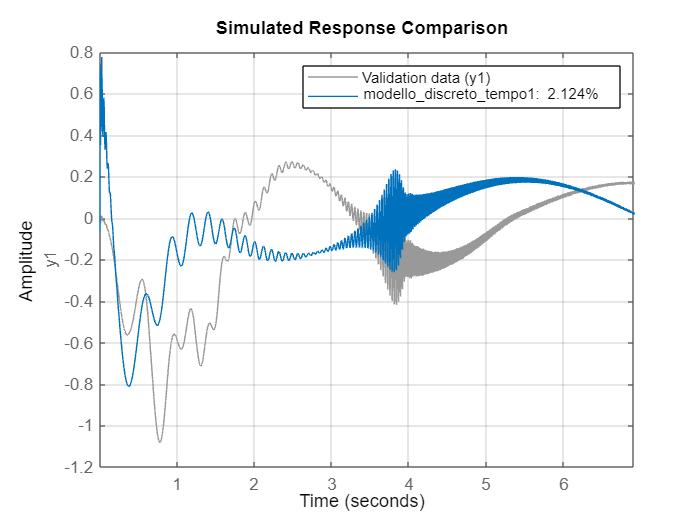

figure
compare(modello_discreto_tempo1,identification1)
grid on

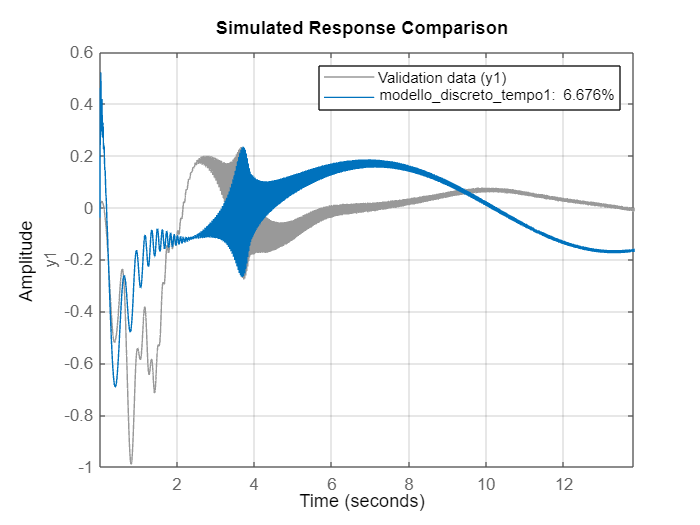

figure
compare(modello_discreto_tempo1,validation1)
grid on